# Heat flow on a dumbbell graph

Solve the heat equation 


$$u_t = \triangle u$$


on a dumbbell graph.

The standard Crank-Nicholson method with time step $h$ is:

$u_{k+1} = \left(I - \frac{h}{2}\triangle\right)^{-1}
 \left(I +\frac{h}{2}\triangle\right) u_k$.

We must modify that to ensure that $u_{k+1}$ satisfies the discrete vertex conditions. In the notation of the paper we let


$$\mathbf{A}_+  = \binom{\mathbf{L}_{\rm int} - \frac{h}{2} \mathbf{P}_{\rm int}} {\mathbf{M}_{\rm VC}} \\
\mathbf{A}_- =  \binom{\mathbf{L}_{\rm int} + \frac{h}{2} \mathbf{P}_{\rm int}} {\mathbf{0}} $$


and then iterate

$\mathbf{A}_+ u_{k+1} = \mathbf{A}_- u_k$.

## Set up the graph and the initial condition

Phi=quantumGraphFromTemplate('dumbbell');
f0=@(x)(2-2*cos(x-pi/3));
f1=1;
f2=@(x)cos(x);
y=Phi.applyFunctionsToAllEdges({f0,f1,f2});

## Set up the time stepping

h=0.01;
tPlot=0.5;
tFinal=10;
nSkip=tPlot/h;
nStep=tFinal/h;

## Set up places to save data

t=0:tPlot:tFinal;
nSave=length(t);
Y=zeros(length(y),nSave);
totalHeatVector=zeros(size(t));
totalHeatVector(1)=Phi.integral(y);

## Set up the evolution matrices

Lint=Phi.wideLaplacianMatrix;
Pint=Phi.interpolationMatrix;
Lplus=Phi.extendWithZeros(Pint+h/2*Lint);
Lminus=Phi.extendWithVC(Pint-h/2*Lint);

## Evolve  the solution

keepCount=1;
for k=1:nStep
    y = Lplus*y;
    y = Aminus\y;
    if mod(k,nSkip)==0
        keepCount=keepCount+1;
        Y(:,keepCount)=y;
        totalHeatVector(keepCount)= Phi.integral(y);
    end
end

## Show that the total heat is conserved

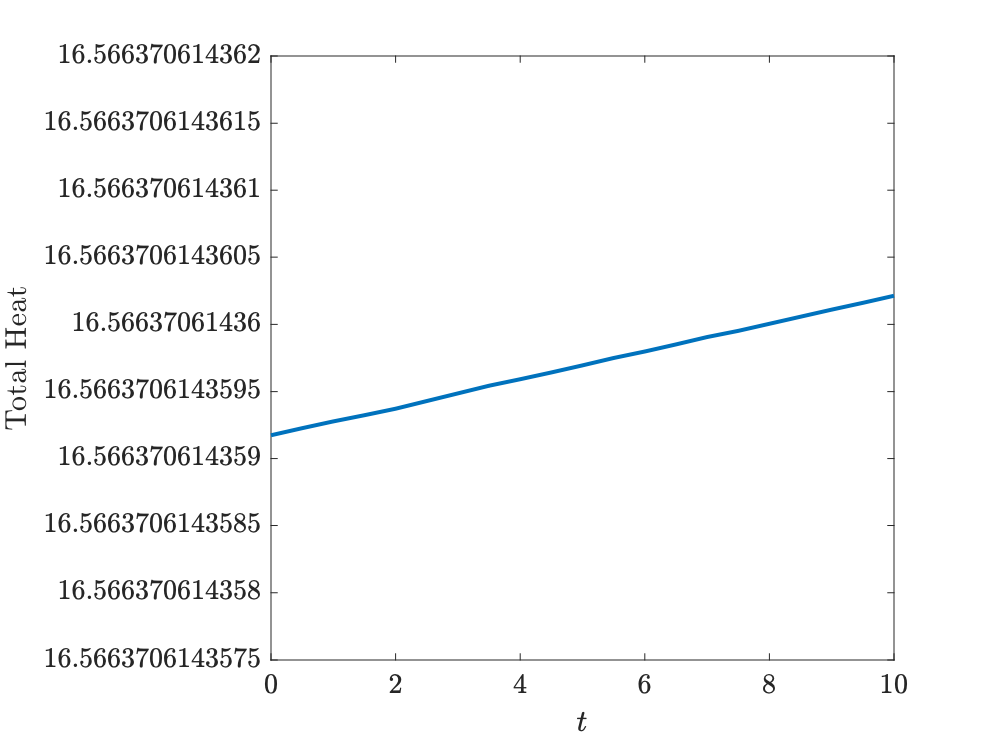

plot(t,totalHeatVector)
xlabel('$t$')
ylabel('Total Heat')

fprintf('Change in heat is %0.2e',max(totalHeatVector)-min(totalHeatVector))

Change in heat is 1.04e-12

## Animate the solution

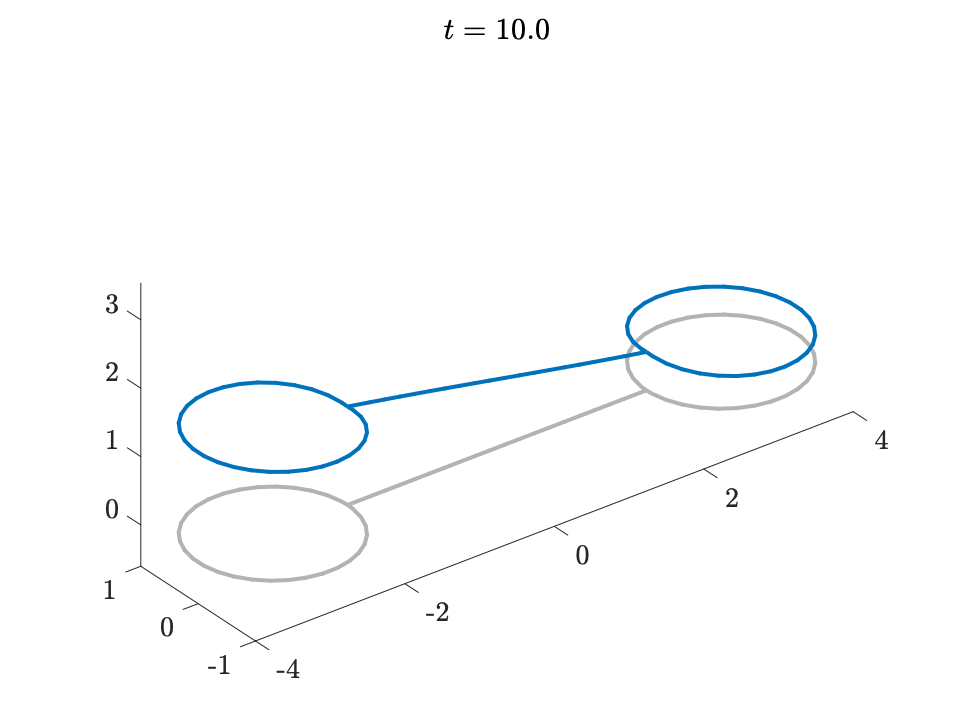

Phi.animatePDESolution(Y,t);